circuit = Circuit('Circuits/RLC.txt');
netlist = circuit.get_netlist

netlist =     'Vcc 3 0 DC Vcc
     Vs 4 1 AC 0
     R2 3 2 1000
     R1 1 0 1000
     C1 4 0 0.000001
     C2 2 4 0.00001
     '


ELAB.analyze(circuit) % Symbolic

Symbolic analysis successful (2.73044 sec).


ELAB.transfer(circuit, 3, 2, false)

Transfer function calculated successfully (3.379780e-02 sec).


$$ans = \frac{v_{2}}{v_{3}}=\frac{\mathrm{Vcc}+C_{1}\,R_{1}\,\mathrm{Vcc}\,s+C_{2}\,R_{1}\,\mathrm{Vcc}\,s+C_{2}\,R_{2}\,\mathrm{Vs}\,s}{\mathrm{Vcc}\,\left(C_{1}\,R_{1}\,s+C_{2}\,R_{1}\,s+C_{2}\,R_{2}\,s+C_{1}\,C_{2}\,R_{1}\,R_{2}\,s^{2}+1\right)}$$

ELAB.evaluate(circuit) % Numerical


Numerical evaluation successful (0.600652 sec).


ELAB.transfer(circuit, 3, 2, true)

Transfer function calculated successfully (1.507653e+00 sec).

ans =
 
     1100 s + 100000
  ---------------------
  s^2 + 2100 s + 100000
 
Continuous-time transfer function.



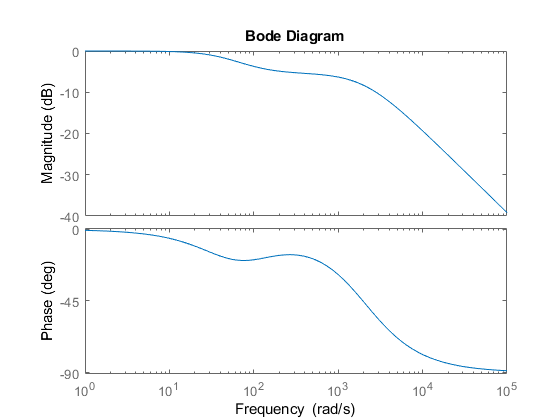

ELAB.bode_plot(circuit)